# Driver Tube Calibrations and Data

% Load in raw Driver tube voltage data before executing 


% Convert Data tables into arrays

% Kcal1 = table2array(Kcal1);
% Kcal2 = table2array(Kcal2);
% Kcal3 = table2array(Kcal3);
% Kcal4 = table2array(Kcal4);
% Kcal5 = table2array(Kcal5);
% Kcal6 = table2array(Kcal6);
% Kcal7 = table2array(Kcal7);
% 
% Dcal1 = table2array(Dcal1);
% Dcal2 = table2array(Dcal2);
% Dcal3 = table2array(Dcal3);
% Dcal4 = table2array(Dcal4);
% Dcal5 = table2array(Dcal5);

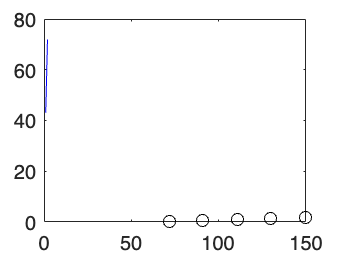

% Plot Driver tube and Kulite calibration curves

Dcal_points = [sum(Dcal1)./(height(Dcal1)), sum(Dcal2)./(height(Dcal2)), sum(Dcal3)./(height(Dcal3)), sum(Dcal4)./(height(Dcal4)), sum(Dcal5)./(height(Dcal5))];
Dcal_pressures = [71.9 91.0 110.8 130.1 150.2];


Kcal_points = [sum(Kcal1)./(height(Kcal1)), sum(Kcal2)./(height(Kcal2)), sum(Kcal3)./(height(Kcal3)), sum(Kcal4)./(height(Kcal4)), sum(Kcal5)./(height(Kcal5)), sum(Kcal6)./(height(Kcal6)), sum(Kcal7)./(height(Kcal7))];
Kcal_pressures = [35.65 22.38 18.18 14.55 10.09 5.80 4.80];



plot(Dcal_pressures, Dcal_points,'ko')
hold on
plot(Dcal_fit, 'b-')
hold off

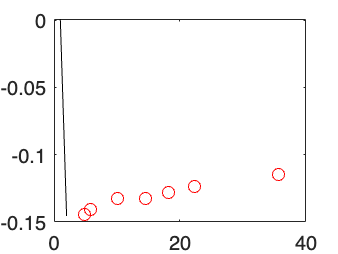


plot(Kcal_pressures, Kcal_points, 'ro')
hold on
plot(Kcal_fit, 'k-')
hold off

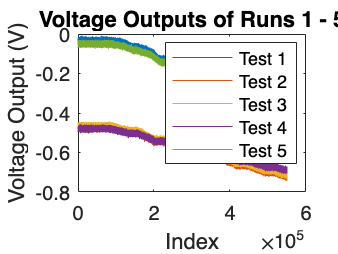

% Plots of Test Run Driver Tube Pressures
figure;

plot(Run1_DT, width(Run1_DT), 'DisplayName', 'Test 1');
hold on;
plot(Run2_DT, width(Run2_DT), 'DisplayName', 'Test 2');
plot(Run3_DT, width(Run3_DT), 'DisplayName', 'Test 3');
plot(Run4_DT, width(Run4_DT), 'DisplayName', 'Test 4');
plot(Run5_DT, width(Run5_DT), 'DisplayName', 'Test 5');

% Adding labels and legend
title('Voltage Outputs of Runs 1 - 5');
xlabel('Index');
ylabel('Voltage Output (V)');
legend('show');

hold off;

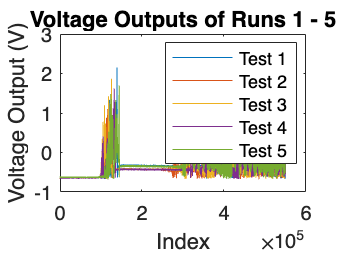

% Plots of Test Run Kulite Pressures

figure;

plot(Run1_K, width(Run1_K), 'DisplayName', 'Test 1');
hold on;
plot(Run2_K, width(Run2_K), 'DisplayName', 'Test 2');
plot(Run3_K, width(Run3_K), 'DisplayName', 'Test 3');
plot(Run4_K, width(Run4_K), 'DisplayName', 'Test 4');
plot(Run5_K, width(Run5_K), 'DisplayName', 'Test 5');

% Adding labels and legend
title('Voltage Outputs of Runs 1 - 5');
xlabel('Index');
ylabel('Voltage Output (V)');
legend('show');

hold off;